# SLCO4A - Aula Prática 8

## Séries de Fourier

### Ortogonalidade de sinais exponenciais complexos

Suponha que $x_m \left(t\right)$ e $x_k \left(t\right)$são dois sinais periódicos contínuos complexos com período $T$. O produto interno $<x_m \left(t\right),x_k \left(t\right)>$ é dado por


$$<x_m \left(t\right),x_k \left(t\right)>\;=\int_{t_0 }^{t_0 +T} x_m \left(t\right)x_k^* \left(t\right)\;\textrm{dt}=\left\lbrace \begin{array}{ll}
T & k=m\\
0 & k\not= m
\end{array}\right.$$


Se o produto interno for nulo para $m\not= k$, os sinais $x_m \left(t\right)$ e $x_k \left(t\right)$são ortogonais.

**Exercício 1:** Considere os sinais $x\left(t\right)=e^{\textrm{j3}\left(\frac{2\pi \;}{T}\right)t}$ e ${y\left(t\right)=e}^{\textrm{j5}\left(\frac{2\pi \;}{T}\right)t}$. Verifique a ortogonalidade dos sinais.

syms t T 
w = (2*pi)/T;
x = exp(j*3*w*t);
yc = exp(-j*5*w*t); %y conjugado
prod_int = int(x*yc, t, 0, T)

$$prod\_int = 0$$

xc = exp(-j*3*w*t);
y = exp(j*5*w*t);
prod_int = int(y*xc, t, 0, T)

$$prod\_int = 0$$

prod_int2 = int(x*xc, t, 0, T)

$$prod\_int2 = T$$

### Séries de Fourier na forma exponencial complexa

$x\left(t\right)=\sum_{k=-\infty }^{\infty } a_k e^{\mathrm{jk}\omega_0 t}$, $t\in \left\lbrack t_0 ,t_0 +T\right\rbrack$

Os coeficientes complexos da série de Fourier são dados por:


$$a_k =\frac{1}{T}\int_{t_0 }^{t_0 +T} x\left(t\right)e^{-\mathrm{jk}\omega_0 t} \mathrm{dt}$$


Cada coeficiente complexo $a_k$ corresponde à projeçao do sinal $x\left(t\right)$ sobre a componente ortogonal $e^{\textrm{jk}\omega_0 t}$ e indica o conteúdo do espectro do sinal na frequência $k\omega_{0\;}$, que é conhecida como *k-ésima * harmônica.

Enquanto que $a_0$ é um número real que corresponde a uma constante e é denominada como componente DC do sinal.

**Exercício 2: **Expanda o sinal $x\left(t\right)=e^{-t}$, $0\le t\le 3$, em série de Fourier na forma exponencial complexa, considerando os seguintes termos de aproximação: 3, 11, 41 e 201.

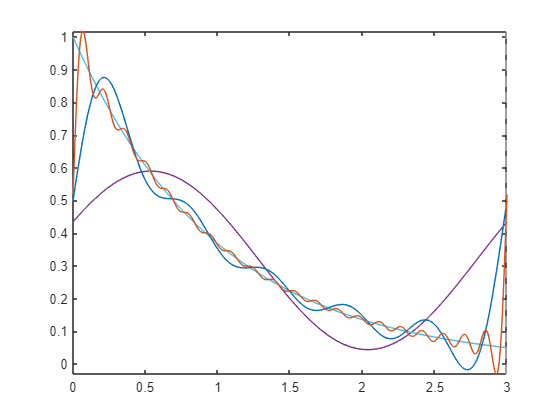

t0 = 0;
T = 3;
w = (2*pi)/T;
syms t
x = exp(-t);
fplot(x, [t0 T])
hold on
%Aproximações 

%coeficientes da serie de fourier 

%3 termos
for k = -1:1
    a(k + 2) = 1/T * int(x*exp(-j*k*w*t), t, t0, t0+T);
end
for k = -1:1
    ex(k+2) = exp(j*k*w*t);
end

xx = sum(a.*ex); %x(t) aproximado para 3 termos
fplot(xx, [t0, t0+T])
%11 termos
for k = -5:5
    a(k + 6) = 1/T * int(x*exp(-j*k*w*t), t, t0, t0+T);
end
for k = -5:5
    ex(k+6) = exp(j*k*w*t);
end

xx11 = sum(a.*ex); %x(t) aproximado para 11 termos
fplot(xx11, [t0, t0+T])
%41 termos
for k = -20:20
    a(k + 21) = 1/T * int(x*exp(-j*k*w*t), t, t0, t0+T);
end
for k = -20:20
    ex(k+21) = exp(j*k*w*t);
end

xx41 = sum(a.*ex); %x(t) aproximado para 41 termos
fplot(xx41, [t0, t0+T])

%Testar 201


### Séries de Fourier na forma trigonométrica

$x\left(t\right)=a_0 +\sum_{n=1}^{\infty } b_n \cos \left(n\omega_0 t\right)+\sum_{n=1}^{\infty } c_n \mathrm{sen}\left(n\omega_0 t\right)$, $t\in \left\lbrack t_0 ,t_0 +T\right\rbrack$

Os coeficientes da série de Fourier na forma trigonométricasão dados por:


$$a_0 =\frac{1}{T}\int_{t_0 }^{t_0 +T} x\left(t\right)\mathrm{dt}$$



$$b_n =\frac{2}{T}\int_{t_0 }^{t_0 +T} x\left(t\right)\cos \left(n\omega_0 t\right)\mathrm{dt}$$



$${\;c}_n =\frac{2}{T}\int_{t_0 }^{t_0 +T} x\left(t\right)\mathrm{sen}\left(n\omega_0 t\right)\mathrm{dt}$$


**Exercício 3: **Considere o sinal do exercício 2. Expanda o sinal $x\left(t\right)=e^{-t}$, $0\le t\le 3$, em série de Fourier na forma trigonométrica, utilizando uma aproximação com a seguinte quantidade de termos: 6, 21 e 201.

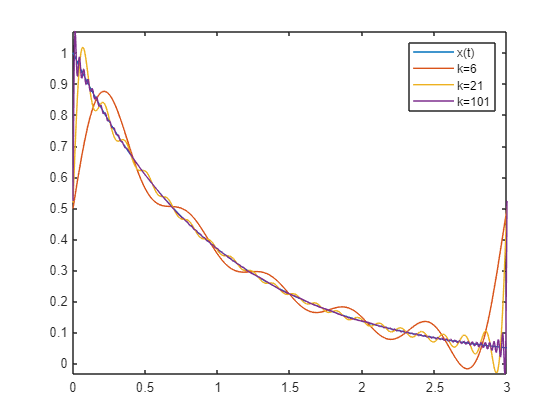

clear all 
close all
T = 3;
t0 = 0;
w = 2*pi/T;
syms t 
x = exp(-t);
figure 
fplot(x, [t0, t0 + T])
hold on
%Aproximações 

%Coeficientes da serie de fourier trigonometrica
a0 = (1/T) * int(x, t, t0, t0+T);
%6 termos => a0, a1, ..., a5

for n= 1:5
    b(n) = (2/T) * int(x*cos(n*w*t), t, t0, t0+T);
    c(n) = (2/T) * int(x*sin(n*w*t), t, t0, t0+T);
end

k = 1:5;
xx6 = a0 + sum(b.*cos(k*w*t) + c.*sin(k*w*t));
fplot(xx6, [t0, t0+T])

%21 termos => a0, a1, ..., a21
for n= 1:20
    b(n) = (2/T) * int(x*cos(n*w*t), t, t0, t0+T);
    c(n) = (2/T) * int(x*sin(n*w*t), t, t0, t0+T);
end

k = 1:20;
xx21 = a0 + sum(b.*cos(k*w*t) + c.*sin(k*w*t));
fplot(xx21, [t0, t0+T])
%101 termos => a0, a1, ..., a100
for n= 1:100
    b(n) = (2/T) * int(x*cos(n*w*t), t, t0, t0+T);
    c(n) = (2/T) * int(x*sin(n*w*t), t, t0, t0+T);
end

k = 1:100;
xx101 = a0 + sum(b.*cos(k*w*t) + c.*sin(k*w*t));
fplot(xx101, [t0, t0+T])
legend("x(t)", "k=6", "k=21", "k=101")

### Séries de Fourier na forma de cosseno e fase

A terceira forma da série de Fourier é usando a propriedade trigonométrica


$$b_k \cos \left(k\Omega_0 t\right)+c_k \textrm{sen}\left(k\Omega_0 t\right)=A_k \cos \left(k\Omega_0 t+{\Theta \;}_k \right)$$


O sinal $x\left(t\right)$ que é definido no intervalo $\left\lbrack t_0 ,t_0 +T\right\rbrack$ é expresso como


$$x\left(t\right)=a_0 +\sum_{k=1}^{\infty } A_k \cos \left(k\Omega_0 t+\Theta_k \right)$$



$$a_0 =\frac{1}{T}\int_{t_0 }^{t_0 +T} x\left(t\right)\textrm{dt}$$


$A_k =\sqrt{\;b_k^2 +c_k^2 }$, $k=1,2,\ldotp \ldotp \ldotp$


$${\Theta \;}_k =\left\lbrace \begin{array}{ll}
{\textrm{tg}}^{-1} \left(-\frac{c_k }{b_k }\right)={\textrm{tg}}^{-1} \left(\frac{c_k }{b_k }\right) & k=1,2,\ldotp \ldotp \ldotp b_k \ge 0\\
\pi +{\textrm{tg}}^{-1} \left(-\frac{c_k }{b_k }\right) & k=1,2,\ldotp \ldotp \ldotp b_k <0
\end{array}\right.$$


**Exercício 4**: Expanda o sinal $x\left(t\right)=e^{-t^2 }$, $-2\le t\le 2$ por série de Fourier na forma trigonométrica de cosseno com fase, utilizando uma aproximação de 101 termos.

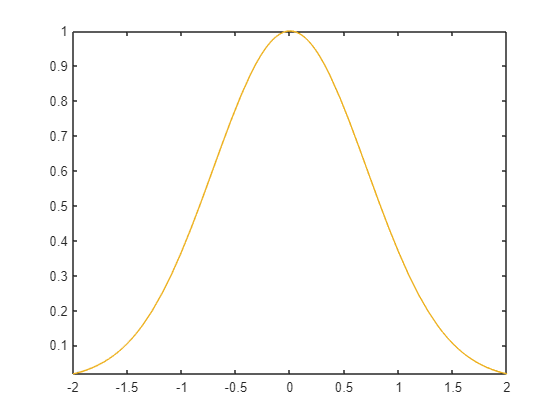

close all
clear all
T = 4;
t0 = -2;
w = 2*pi/T;
syms t n
x = exp(-t^2);
figure
fplot(x, [t0, t0+T])
hold on
%Coeficiente da forma trigonometrica compacta 
a0 = 1/T * int(x, t, t0, t0+T);
b = (2/T) * int(x*cos(n*w*t), t, t0, t0+T);
c = (2/T) * int(x*sin(n*w*t), t, t0, t0+T);

n1 = 1:100;
bn = subs(b,n,n1);
cn = subs(c, n, n1);

%Aproximação por serie de fourier - forma trigonometrica 
xx = a0 + sum(bn.* cos(n1*w*t) + cn.*sin(n1*w*t));
fplot(xx, [t0, t0+T])


%Coeficientes da forma trigonometrica compacta
k = 1:100;
A = sqrt(bn.^2+cn.^2);
Theta = atan2(-cn, bn);
xxc = a0+sum(A.*cos(k*w*t+Theta));
fplot(xxc, [t0, t0+T])

### Representação gráfica dos coeficientes da série de Fourier

T = 3;
t0 = 0;
w = 2*pi/T;
syms t k n
x = exp(-t);
%Coeficientes da serie de fourier na forma complexa
a = (1/T) * int(x*exp(-j*k*w*t), t, t0, t0+T);

k1 = -6:6;
ak = subs(a, k, k1);
figure
stem(k1, abs(ak))
legend("|a_k|")

figure 
stem(k1, angle(ak))
legend("Fase de a_k")